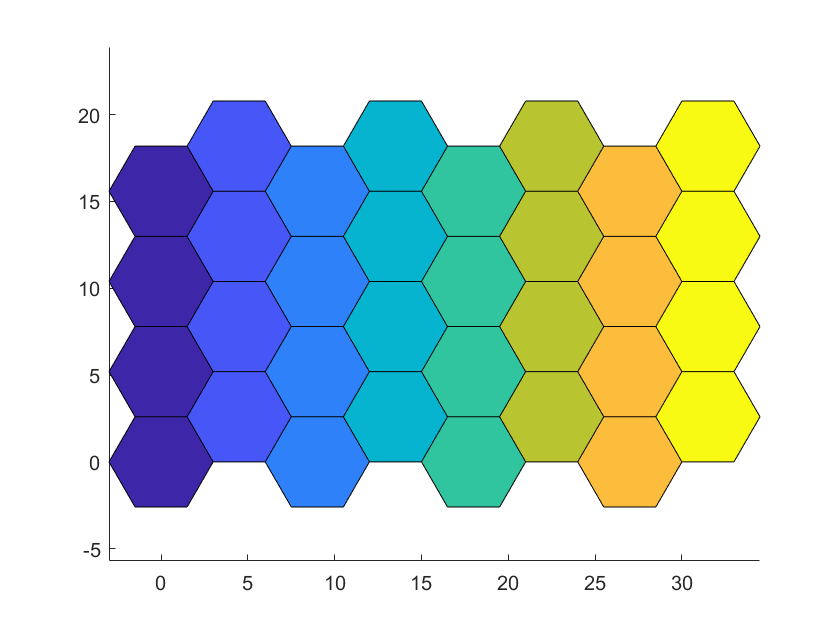


    clf;
    
    r = 3; %distance btwn hexes
    l=4; %len and height of display
    b=4;
    
    
    C0=rand(l,b); %random color
    C1=rand(l,b);
    xhex=[-r/2 -r -r/2 r/2 r r/2]; % x-coordinates of the vertices
    yhex=[r*sqrt(3)/2 0 -r*sqrt(3)/2 -r*sqrt(3)/2 0 r*sqrt(3)/2]; % y-coordinates of the vertices
    
    %%ASA...
   
    %Color Arrays
     for i=1:l
        for j=1:b
            C0(i,l)=i+j/10;
            C1(i,l)=i+0.5 + j/10 +0.1;
        end
    end
     
    
    clf;
    
    % get centers
    
    width=2
    height=2
    if
    for i=1:l
        for j=1:b
            
            
        end
    end
    
    for i=1:l
        for j=1:b
            patch(xhex+(i-1)*3*r,yhex+(j-1)*r*sqrt(3),C0(i,l))
            patch(xhex+3/2*r+(i-1)*3*r,yhex+r*sqrt(3)/2+(j-1)*r*sqrt(3),C1(i,l))
            
            hold on
            
        end
    end
    
    axis equal

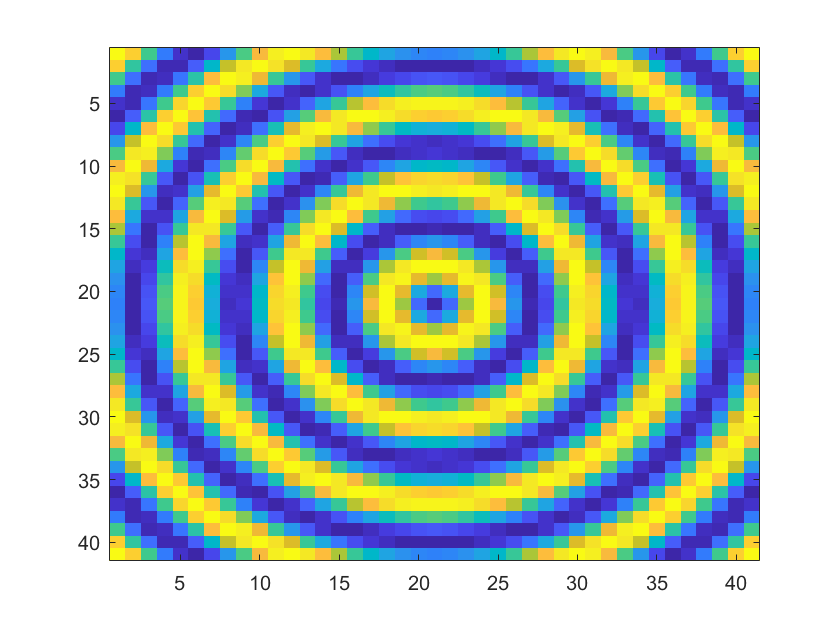

    clf;
    
    
    %Cartesian Sampling
x1 = -10:0.5:10;
y1 = -10:0.5:10;

[x y]= meshgrid(x1, y1);
f = cos(cos(sqrt(x.^2+y.^2)));
figure;
imagesc(f);

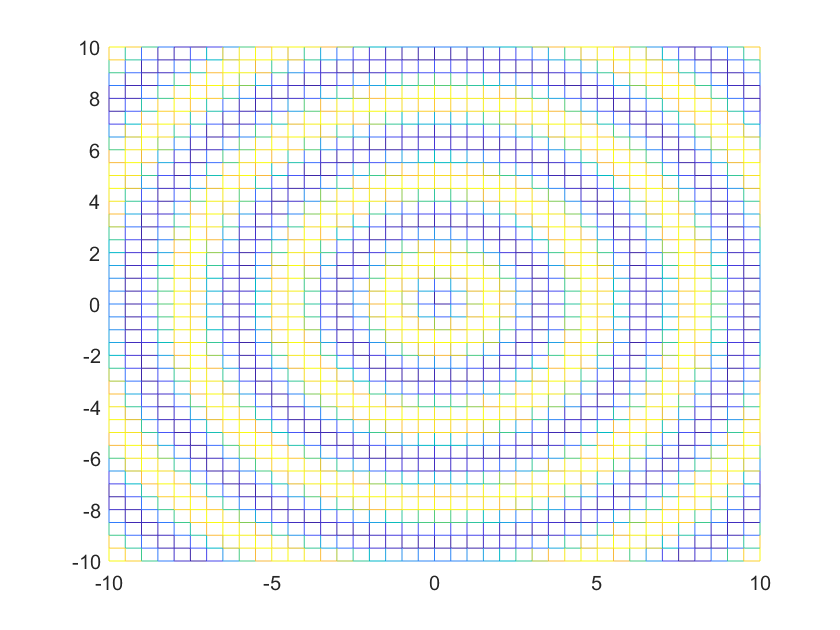

figure
mesh(x,y, f);
view([0 90.000])

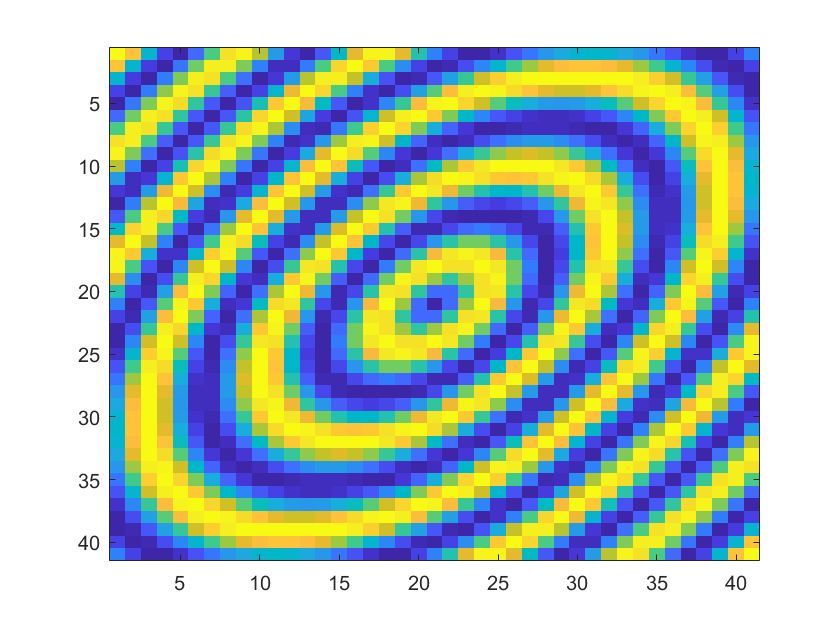


%the sampling lattice is
%[x y]’ = |sqrt(3)/2 0| |i|
% |1/2 1| |j|
%hexagonal smapling
i = x;
j = y;
x = i*sqrt(3)/2 +0;
y = i*1/2 + j;
%x = i*sqrt(3)/2 +0;
f = cos(cos(sqrt(x.^2+y.^2)));
figure;
imagesc(f);

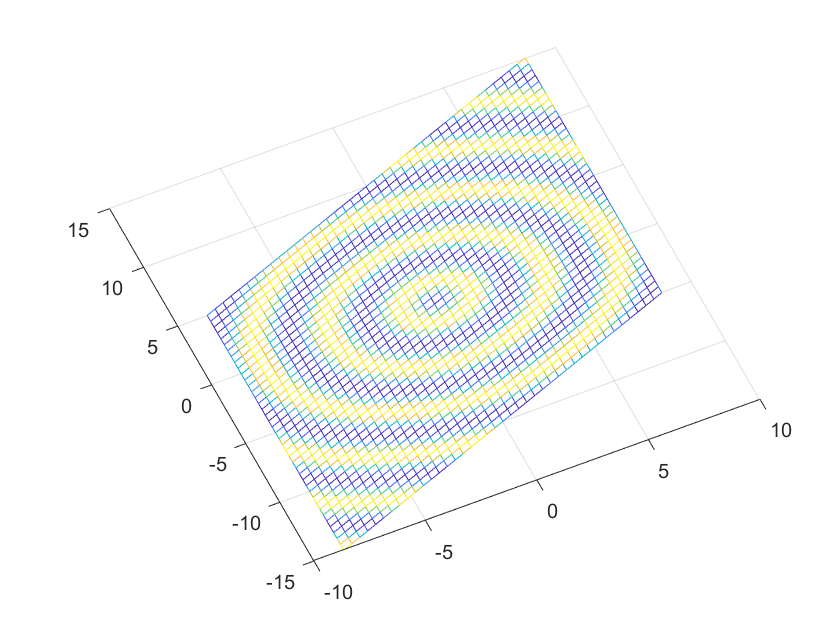

figure
mesh(x,y, f);

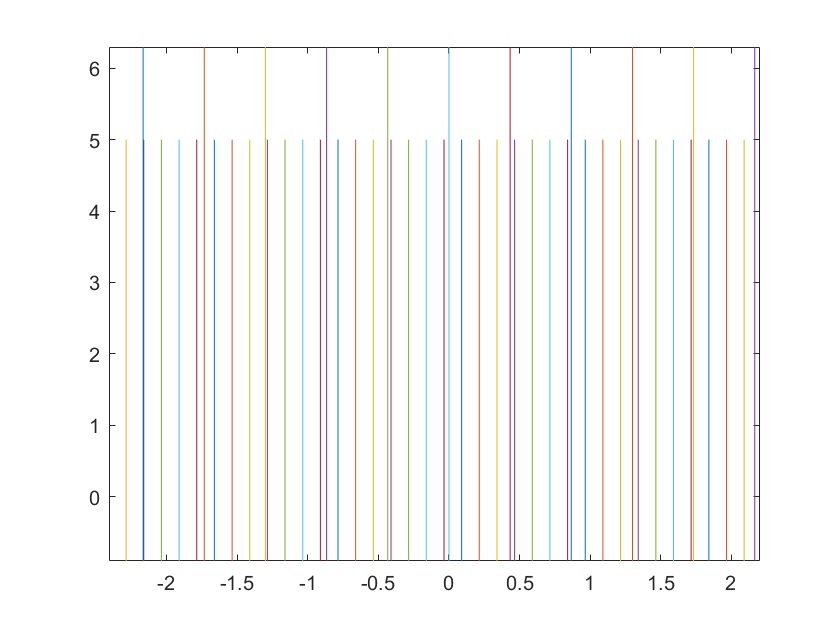


%TRYING TO RECOVER ORIGNAL SAMPLING
%i = -20:0.1/1.5:20;
minx = min(x(:));
maxx = max(x(:));
miny = min(y(:));
maxy = max(y(:));

miny = y(1,end);
maxy = y(end,1);

i = minx:0.5/4:maxx;
j = miny:0.5/4:maxy;
%j = -20:0.1:20;

[x2d y2d]= meshgrid(i, j);
figure;
plot(x2d,y2d);hold on; plot(x,y)


v = zeros(size(x2d));
for i=1:size(x2d,1)
i
for j=1:size(x2d,2)
b = boxSplineD2(x-x2d(i,j),y- y2d(i,j));
v(i,j)= sum(sum(b.*f));

end
end

i = 1

Undefined function or variable 'boxSplineD2'.


figure;
imagesc(v);
figure
mesh(x2d,y2d, v);
    